s=tf('s');
[kk,aa,TT]=ndgrid([2,5],[10,10],[0,0.1]); % define parameter grid
kk=kk(:); aa=aa(:); TT=TT(:); % make them column vectors
for i=1:length(kk) % define array of SISO plants
 P(1,1,i)=kk(i)*exp(-s*TT(i))/(s/aa(i)+1)
end

P =
 
    20
  ------
  s + 10
 
Continuous-time transfer function.


P(:,:,1,1) =
 
    20
  ------
  s + 10
 

P(:,:,2,1) =
 
    50
  ------
  s + 10
 
2x1 array of continuous-time transfer functions.


P(:,:,1,1) =
 
    20
  ------
  s + 10
 

P(:,:,2,1) =
 
    50
  ------
  s + 10
 

P(:,:,3,1) =
 
    20
  ------
  s + 10
 
3x1 array of continuous-time transfer functions.


P(:,:,1,1) =
 
    20
  ------
  s + 10
 

P(:,:,2,1) =
 
    50
  ------
  s + 10
 

P(:,:,3,1) =
 
    20
  ------
  s + 10
 

P(:,:,4,1) =
 
    50
  ------
  s + 10
 
4x1 array of continuous-time transfer functions.


P(:,:,1,1) =
 
    20
  ------
  s + 10
 

P(:,:,2,1) =
 
    50
  ------
  s + 10
 

P(:,:,3,1) =
 
    20
  ------
  s + 10
 

P(:,:,4,1) =
 
    50
  ------
  s + 10
 

P(:,:,5,1) =
 
                  20
  exp(-0.1*s) * ------
                s + 10
 
5x1 array of continuous-time transfer functions.


P(:,:,1,1) =
 
    20
  ------
  s + 10
 

P(:,:,2,1) =
 
    50
  ------
  s + 10
 



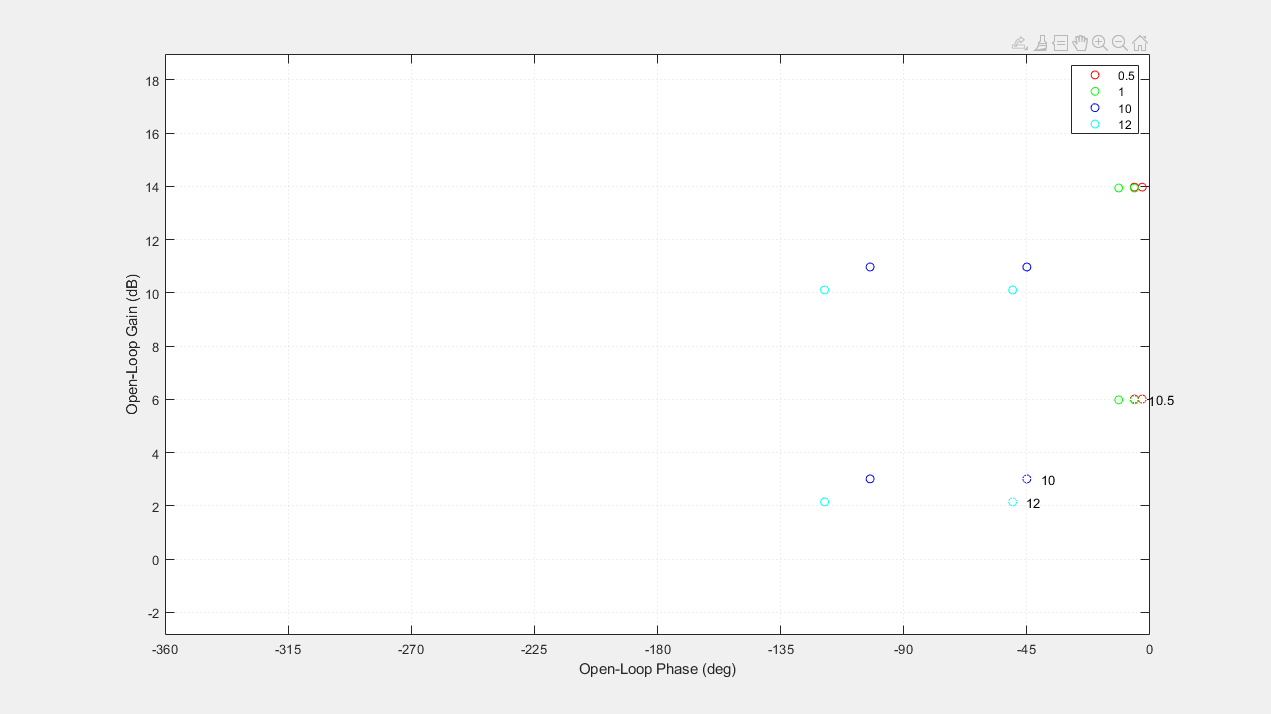

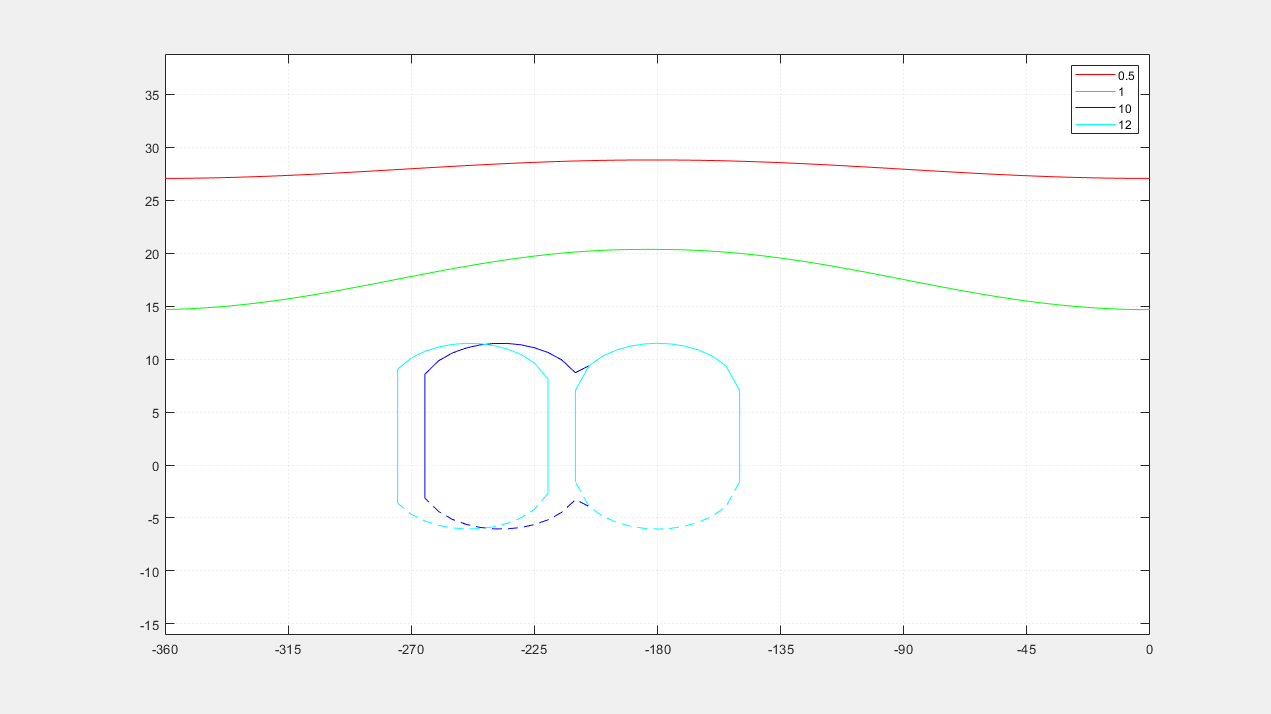

w=[0.5,1,10,12]; % define frequency points
plottmpl(w,P) % draws the plant templates
bnds=sisobnds(2,[0.5,1,10,12],10.^([-20,-10,6,6]/20),P,[],6);
plotbnds(bnds)

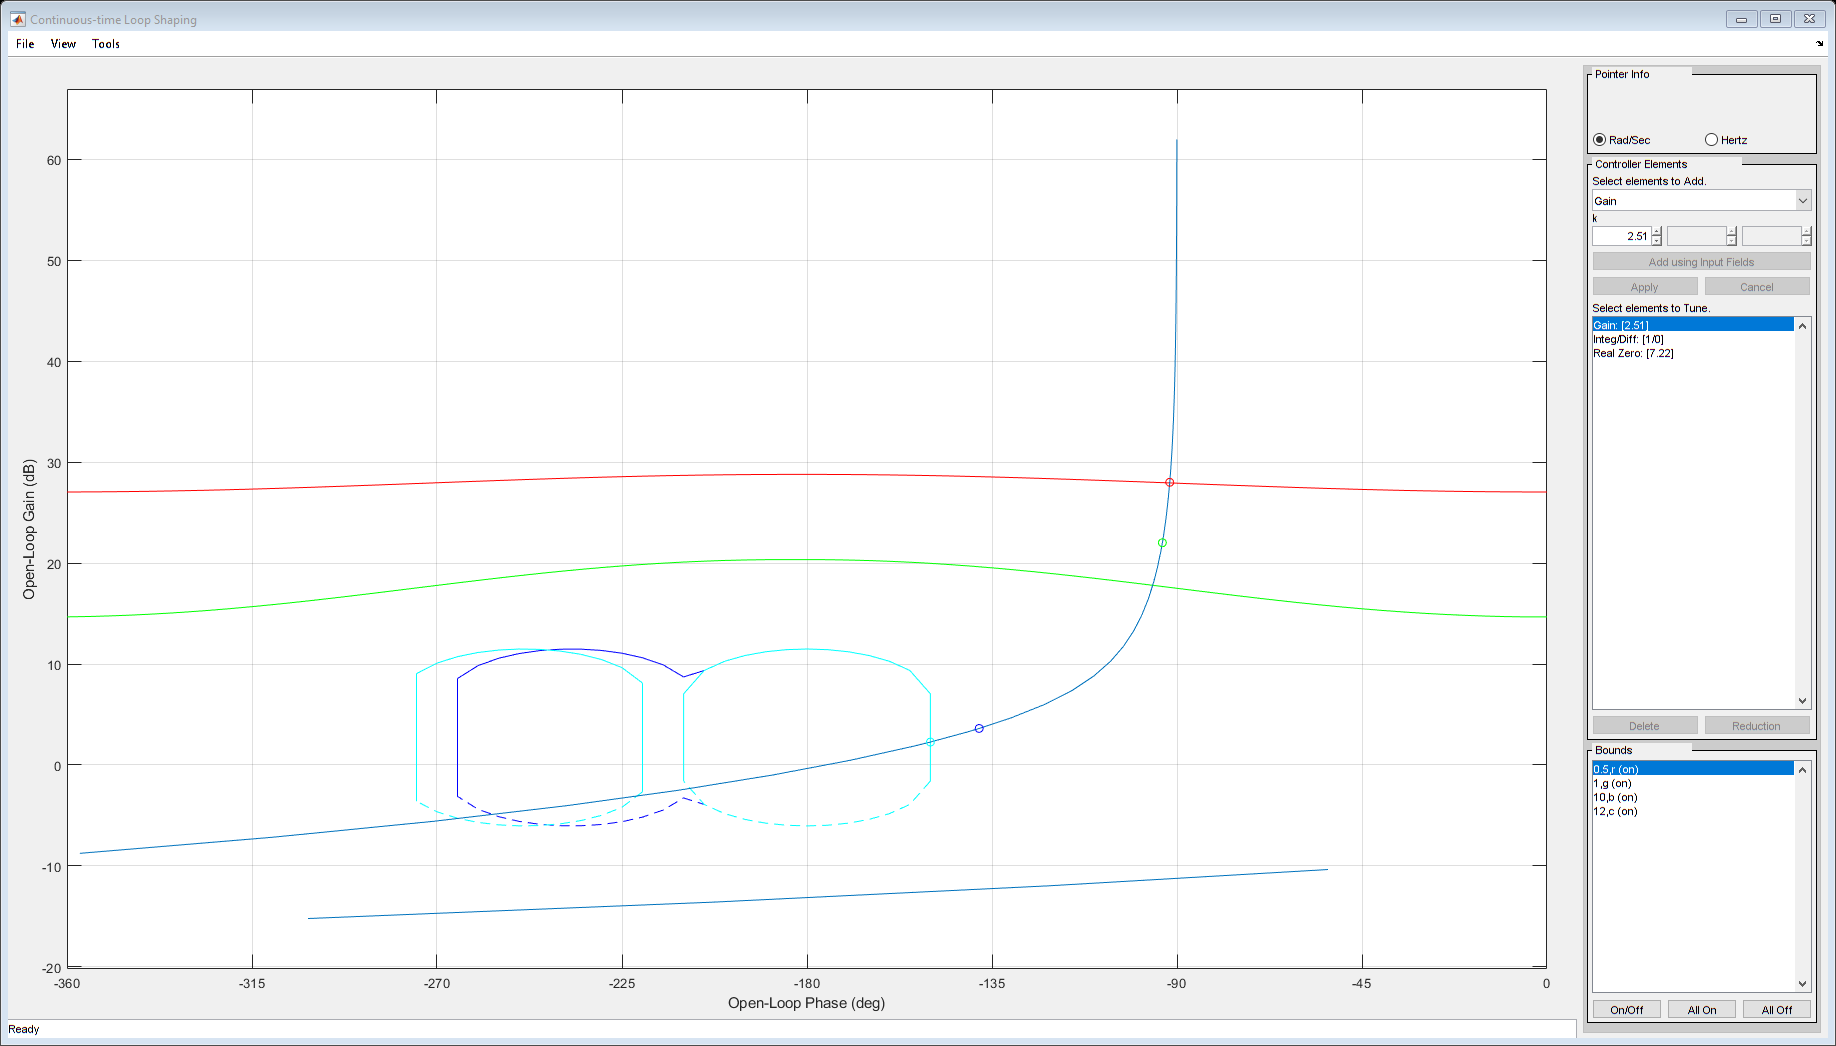

% G=2*(s/6+1)/s;
lpshape(logspace(-2,2),bnds,P(1,1,6),G) % do the design!